clear;clc;
close all;

folderPath = fullfile(pwd, '250424-M-Kernel-bloch');
if ~exist(folderPath, 'dir')
mkdir(folderPath);
end

data.basic.gamma = 2.6752e+08;  % [rad/s/T] Gyromagnetic Ratio 
data.basic.B0 = 48000e-9; 
data.basic.Delta = 0;  % [rad/s] Resonance frequency offset
data.basic.theta = 0;  % [°] The phase of excitation field
data.basic.T1relax = 500;  % [ms] Longitudinal relaxation time T1
data.basic.T2relax = 500;  % [ms] Transversal relaxation time T2
data.basic.T2relax_eff = 100;  % [ms] Effective transverse relaxation time T2*

data.basic.trep = 400;  
% Meaning of 'trep' depends on the pulse sequence type:
% - FID  : Total duration of the sequence (including excitation and signal acquisition)
% - SE   : Sum of the 90° excitation pulse duration and relaxation (echo) time
% - SSFP : Periodic repetition interval between successive RF excitations

data.basic.tp = 20;  % [ms] Single cycle excitation time
data.basic.fs = 1000;  % [Hz] Sampling frequency

data.basic.B1 = 1e-7;  % [T] The amplitude of the alternating field in the x–y plane

tic;
jlmrsData.measure.pulse_type = 'SSFP'

jlmrsData = 包含以下字段的 struct :
    measure: [1×1 struct]


% Parameters of the Bloch equation for a steady-state precession sequence
odeparam = [];  
odeparam.gamma = data.basic.gamma; 
odeparam.B1 = data.basic.B1;
odeparam.Delta = data.basic.Delta; 
odeparam.theta = data.basic.theta;
odeparam.T1 = data.basic.T1relax/1e3;
odeparam.T2 = data.basic.T2relax/1e3;
odeparam.T2_eff = data.basic.T2relax_eff/1e3;
odeparam.pulseparam.trep = data.basic.trep/1e3;
odeparam.pulseparam.tp = data.basic.tp/1e3;
odeparam.pulseparam.fs = data.basic.fs;

% SD-MEI algorithm to solve the magnetization vector
switch jlmrsData.measure.pulse_type
    case 'FID'
        M_data = SDMEI_BLOCH_FID_Mt(odeparam);  
    case 'SE'
        M_data = SDMEI_BLOCH_SE_Mt(odeparam);
    case 'SSFP'
        M_data = SDMEI_BLOCH_SSFP_Mt(odeparam);
end
% Extract the magnetization vector of the Mxy component of interest

elapsedTime = toc;
fprintf('Time: %.2f 秒\n', elapsedTime);

Time: 0.04 秒


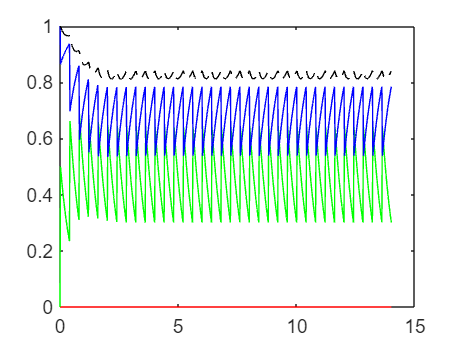

% Draw the magnetization vector diagram
figure
plot(M_data(1, :), M_data(2, :),'r', M_data(1, :), M_data(3, :), 'g', ...
    M_data(1, :), M_data(4, :),'b', ...
    M_data(1, :), sqrt(M_data(2, :).^2+M_data(3, :).^2+M_data(4, :).^2),'--k')

% save(fullfile(pwd, ['100-1000-100-bloch-250507','.mat']), ...
%     "B1",'m_ssfp');